clc; clear; close all
% ******************** + Parametros del sistema  + ********************
 % Tiempo de muestreo
T = 0.01;                
% modelo del sistema en su funcion de transferencia
s = tf('s');
G = 4.228 / ((s+0.5) * (s^2 + 1.64*s + 8.456))     % G1 de ejemplo

G =
 
               4.228
  --------------------------------
  s^3 + 2.14 s^2 + 9.276 s + 4.228
 
Continuous-time transfer function.



%G = 27 / ((s+1)*(s+3)^3);                          % G2 de ejemplo
%G = exp(-0.5*s)/((s+1)^2)                          % G3 de ejemplo

% modelo del sisteam en espacio de estados
H = c2d(G,T);
[num,den] = tfdata(H,'v');
[A, B, C, D] = tf2ss(num,den)

A =     2.9779   -2.9567    0.9788
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C = 	1.0e+-5 *

    0.0701    0.2788    0.0693


D = 0


% *******************************  ZN  **************************************
Ku = 3.665;
Tu = 2.06;
%Ku = 5.12;
%Tu = 2.06;
%Ku = 4.68;
%Tu = 3.28;
% ********************* + Parametros del controlador + **********************
Kp = 0.6 * Ku

Kp = 2.1990

Ki = 1.2 * Ku / Tu;
Kd = 0.6 * Ku * Tu /  8;

Ti = Kp/Ki

Ti = 1.0300

Td = Kd/Kp

Td = 0.2575

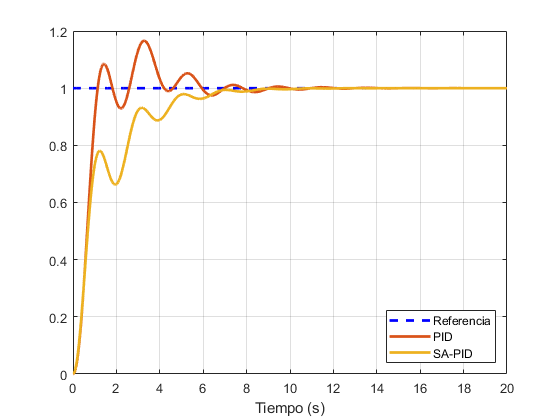

% ********************* + Definicion de la funciond de costo + *************
Gains = [Kp Ki Kd] ;   

Kpmin = 0.533 * Kp; % 0.32 * Ku;
Kpmax =    1  * Kp; % 0.60 * Ku;
Kdmin = 1.067 * Kd; % 0.08 * Ku * Tu;
Kdmax =     2 * Kd; % 0.15 * Ku * Tu;
Kimin =  0.01 * Ki;
Kimax =  0.85 * Ki;

range_gains = [Kpmin Kpmax Kdmin Kdmax Kimin Kimax];
% ******************** PID ***************************
ref = 1;
[y1,t1] = PIDcontrol(G,ref,Gains,T);
%*************************************************************

ObjectiveFunction = @(Gains)CalculeCost(G,ref,Gains,T);    % Funcion Objetivo


% ************************* Parametros SA ********************************** 

iter = 50;        % Nnmero de iterationes
subiter = 5;      % Numero of Sub-iterationes
T0 = 0.025;       % Temperatura inicial
alpha = 0.99;     % Temp. Reduction Rate


% ************************* Inicializacion *******************************

sol.Gain = [Kp Ki Kd];
sol.Cost = ObjectiveFunction(Gains);
BestSol = sol;                  % mejor solucion inicial encontrada
BestCost = zeros(iter, 1);      % vector de los mejores valores de costo
T = T0;                         % temperatura inicial
for i = 1:iter
    for subit = 1:subiter   
        % Creacion de una nueva solucion
        newsol.Gain = CreateNeighbor(sol.Gain,range_gains);
        newsol.Cost = ObjectiveFunction(newsol.Gain);
        if newsol.Cost <= sol.Cost % verificamos si la nueva solicion es mejor
            sol = newsol;
        else % si no es mejor solucion
            DELTA = (newsol.Cost-sol.Cost)/sol.Cost;
            P = exp(-DELTA/T);
            if rand <= P
                sol = newsol;
            end
        end
        %  actualizamos la mejor solucion encontrada
        if sol.Cost <= BestSol.Cost
            BestSol = sol;
        end
        
    end
    BestCost(i) = BestSol.Cost;
    %disp(['Iteration ' num2str(i) ': Best Cost = ' num2str(BestCost(i))]);
    T = alpha*T;  % actualizamos el valor de temperatura
end

[y2,t2] = PIDcontrol(G,ref,BestSol.Gain,T);

figure(1)
plot(t1, ref*ones(1,length(t1)),'b--',t1,y1,t2,y2, 'LineWidth', 2); grid on
xlabel('Tiempo (s)')
legend({'Referencia', 'PID','SA-PID'},'Location','southeast')

function [y,t]  = PIDcontrol(G,ref,Gains,dt)
    Kp = Gains(1);
    Ki = Gains(2);
    Kd = Gains(3);
    
    s = tf('s');
    Gc = Kp + Ki/s + Kd*s/(1+.001*s);
    Loop = series(Gc,G);
    ClosedLoop = feedback(Loop,1);
    
    t = 0:dt:20;
    [y,t] = step(ClosedLoop,t);
    y = ref*y;
end

function J = CalculeCost(G,ref,Gains ,T)
    [y,~] = PIDcontrol(G,ref,Gains,T);
    select_costF = 2;
    J = CostFunction(y',ref,select_costF,T);    % Funcion Objetivo
end
